# ROZWIAZYWANIE UKŁADÓW RÓWNAŃ NIELINIOWYCH

## Ogólne zagadnienia wymagane na laboratorium nr 2

## "Wstęp do metod numerycznych"

Opracował: K. Król

**---------------------------------------------------------------------------------------------------------------------------------------------**

**UWAGA! Zaleca się pracować z niniejszym skryptem ustawiając opcję "View" -> "Output on Right"**

**---------------------------------------------------------------------------------------------------------------------------------------------**

**Umiejętności wymagane na laboratorium**

Na laboratorium wymagany jest cały zakres wiedzy wykładowej ze szczególnym uwzględnieniem tematyki rozwiązywania układów równań nieliniowych (dalej po prostu URN). W podstawowym zakresie sprawdzane będzie:

- Czy student zna postać kanoniczną problemu numerycznego p.t. "Rozwiązywanie układu równań nieliniowych"? Czy potrafi poprawnie sprowadzić praktyczny problem opisany takimi równaniami do postaci wejściowej dla metod numerycznych stosowanych w tym zagadnieniu?

- Czy student potrafi zaimplementować w sposób jawny podstawowe metody rozwiązywania pojedynczych równań nieliniowych?

- Czy student potrafi zaimplementować w sposób jawny podstawowe metody rozwiązywania układów równań nieliniowych?

- Czy student rozumie właściwości najczęściej spotykanych metod (w zasadzie wersji podstawowych tych metod)?

- Czy student potrafi zaimplementować w sposób poprawny numerycznie iteracyjne metody rozwiązywania układów równań nieliniowych?

- Czy student rozumie pojęcie zbieżności metody iteracyjnej?

- Czy student potrafi na podstawie otrzymanych dla algorytmu iteracyjnego wyników określić stan algorytmu (zbieżny/rozbieżne, szybkość zbieżności) oraz świadomie wpływać na parametry numeryczne takiego algorytmu (zapewnienie zbieżności, osiągnięcie szybszej zbieżności) poprzez zmianę jego ustawień?

Docelowo student powinien orientować się jakie ogólne właściwości mają poznane metody w świetle wszystkich problemów wymienionych powyżej.

# PODPOWIEDZI IMPLEMENTACYJNE

## POSTAĆ RÓWNANIA

W rzeczywistości nie dysponujemy metodami rozwiązywania równań nieliniowych, a jedynie metodami wyszukiwania zera funkcji nieliniowych i układów takich funkcji. Dlatego też problem rozwiązania układów równań nieliniowych sprowadzamy do problemu szukania zera i postać kanoniczna (spodziewana) danych do wszystkich metod wygląda następująco:


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{x}}\right)=0$$


Przy czym ***f(x)*** zapisane pogrubionym tekstem oznacza, że jest to wektor - wektor funkcji w analogii do postaci kanonicznej metod rozwiązywania równań liniowych. Przykładowo poniższy układ równań nieliniowych:


$$\left\lbrace \begin{array}{ll}
\; & 5x_1^2 +10x_2^2 =5\\
\; & \ln \left(x_1^2 \right)+x_2^2 =-3
\end{array}\right.$$


W postaci kanonicznej będzie wyglądał tak:


$$\left\lbrace \begin{array}{ll}
\; & 5x_1^2 +10x_2^2 -5=0\\
\; & \ln \left(x_1^2 \right)+x_2^2 +3=0
\end{array}\right.$$


A zapisany za pomocą wektora funkcji tak:


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{x}}\right)=\left\lbrack \begin{array}{c}
f_1 \left(x\right)\\
f_2 \left(x\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
5x_1^2 +10x_2^2 -5\\
\ln \left(x_1^2 \right)+x_2^2 +3
\end{array}\right\rbrack$$


Zwróć uwagę, że funkcje tworzące nasz wektor w postaci kanonicznej (czyli ich wzory) to co do zasady nie są te same funkcje które mamy w równaniu. One oczywiście z nich powstały, ale jeżeli weźmiemy pod uwagę to jak działają metody to faktycznie obliczane będą funkcje wewnątrz wektora ***f(x)*** a nie funkcje występujące w równaniu oryginalnym po lewej stronie. 

To co jest istotne w tej różnicy to to, że mogą powstawać funkcje zawierające odejmowanie lub inną równie trudną numerycznie operację, która wprowadza dużą propagację błędu. Przekłada się to na dokładność jaką jesteśmy w stanie uzyskać.

Żeby zrozumieć ten problem należy sobie uświadomić, że wszystkie metody o jakich mówmy są metodami iteracyjnymi i każde kolejne przybliżenie powstaje z poprzedniego. Zatem obliczanie każdej z funkcji wektora ***f(x)*** będzie następowało wielokrotnie, za każdym razem propagując błąd. Kluczowa tutaj będzie zbieżność metody. Dla metod zbieżnych wolno żeby dotrzeć do zakładanej dokładności (np. 1e-10) metoda musi wykonać wiele operacji związanych z propagacją błędu. W konsekwencji może się okazać, że taka metoda nie może uzyskać dużej dokładności. Dlatego stosujemy metody zbieżne szybciej. 

## IMPLEMENTACJA PODSTAWOWYCH METOD 

Jeżeli chodzi o rozwiązywanie układów równań nieliniowych za pomocą metod numerycznych to sytuacja jest trochę prostsza niż w przypadku poznanych już metod rozwiązywania równań liniowych. Podstawową metodą o najszerszym rozpowszechnieniu jest metoda Newtona (czasami nazywana metodą Newtona-Raphsona). Często jednak jest ona zmodyfikowana na różne sposoby i formalnie nosi inne nazwy. W dużej mierze wynika to z poznanych na wykładzie właściwości numerycznych (takich jak np. cykle) oraz sposobów automatycznego radzenia sobie z tego typu problemami. Jednak trzon podejścia numerycznego w znakomitej większości metod implementujących układy równań nieliniowych jest taki sam jak w metodzie podstawowej. 

W ramach wykładu poznaliśmy już kilka wariacji metody Newtona (metoda regula-falsi, metoda siecznych), które są uproszczeniami podstawowej metody. Przekłada się to jednak na ich właściwości numeryczne, w szczególności na właściwości dotyczące parametrów zbieżności. 

W dalszej części wykładu będziemy się zajmować głównie metodami iteracyjnymi, dlatego laboratorium z układów równań nieliniowych jest świetną okazją, żeby zbadać i zaobserwować właściwości numeryczne algorytmów iteracyjnych w ogóle. 

Ponieważ będziemy metody implementować jawnie sami, w zakresie podstawowych metod nie ma jakich szczególnie przydatnych funkcji MATLABA do wykorzystania. Opierać się będziemy w zakresie metod podstawowych na ogólnych umiejętnościach programistycznych i wiedzy z laboratorium 0.

## Prawidłowa implementacja algorytmów związanych z układami równań

W przypadku układów równań nieliniowych w metodzie Newtona (wielowymiarowej) dochodzimy do takiego wzoru ogólnego metody:


$${\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}+1\right)} ={\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}\right)} -\frac{\mathit{\mathbf{f}}\left({\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}\right)} \right)}{\nabla \mathit{\mathbf{f}}\left({\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}\right)} \right)}$$


gdzie $\nabla \mathit{\mathbf{f}}\left({\mathit{\mathbf{x}}}^{\;} \right)$ jest macierzą jakobiego naszego wektora funkcji więc macierzą zdefiniowaną w taki sposób:


$$\nabla \mathit{\mathbf{f}}\left({\mathit{\mathbf{x}}}^{\;} \right)=\left\lbrack \begin{array}{ccc}
\frac{\delta f_1 \left(x\right)}{\delta x_1 } & \cdots  & \frac{\delta f_n \left(x\right)}{\delta x_1 }\\
\vdots  & \ddots  & \vdots \\
\frac{\delta f_1 \left(x\right)}{\delta x_n } & \cdots  & \frac{\delta f_n \left(x\right)}{\delta x_n }
\end{array}\right\rbrack$$


Powstaje jednak problem, który znamy z tematyki układów równań liniowych .Tzn. podzielenie przez macierz to w rzeczywistości mnożenie przez odwrotność tej macierzy, a odwracanie macierzy jest operacją źle uwarunkowaną (może generować olbrzymie błędy oraz być bardzo wolne). Dlatego przykładowa poniższa implementacja algorytmu Newtona dwuwymiarowego choć zgodna ze wzorem nie jest poprawna numerycznie:

%Przypuśćmy, ze szukamy przecięcia okręgu o środku w p. (a,b) i promieniu
%r:



$${\left(x_1 -a\right)}^2 +{\left(x_2 -b\right)}^2 =r^2$$


% Z prostą:



$$x_1 =x_2$$


% Stosuję tutaj notację wielowymiarową, gdzie zamiast xyz stosuję x1, x2,
% x3. Więc nasza prosta to po prostu y=x w notacji "literowej"

%Przyjmijmy, że środek okręgu jest w p. (0,0) i promieniu 3
a=0;
b=0;
r=3;

% Przykładowy wektor funkcji, zwróć uwagę, że x tutaj jest wektorem składającym się 
% ze zmiennych x1, x2..., a nie skalarem
f1=@(x) (x(1)-a)^2+(x(2)-b)^2-r^2;
f2=@(x) x(1)-x(2);

%Nasz wektor funkcji (nie jest potrzebny do programu) koncepcyjnie
%wyglądałby tak:
%f_wektor = [f1, f2];

%Jakobian zaimplementowany w postaci analitycznej:
f1_x1 = @(x)2.*x(1)
f1_x2 = @(x)2.*x(2)
f2_x1 = @(x)1
f2_x2 = @(x)-1

% ... wyglądałby następująco jako macierz:
%J=[f1_x1, f1_x2;... 
%   f2_x1, f2_x2];

%Implementacja prostej metody Newtona (niepoprawna numerycznie)
x0 = [1;2];             %punkt startowy
expected_error = 1e-6;  %zakładana dokładność

x=x0;iterations=0;
%Jako miarę błędu przyjmujemy odległość pomiędzy spodziewanym rozwiązaniem
%(f1=0, f2=0), a aktualnym rozwiązaniem, ale mogą być przyjęte inne miary
%błędu np. różnica miedzy dwoma iteracjami. 
% UWAGA! Zawsze ograniczaj liczbę iteracji w praktycznych kodach
while (norm([f1(x), f2(x)])>expected_error & iterations<100)
    J=[f1_x1(x), f1_x2(x);...     %Obliczamy liczbowa wartość Jakobianu w tej iteracji
       f2_x1(x), f2_x2(x)];
    f = [f1(x), f2(x)];           %Obliczamy liczbową wartość wektora funkcji w tej iteracji
    
    x=x-inv(J)*f';                %JAWNIE ODWRACAMY MACIERZ JAKOBIEGO
    
    iterations=iterations+1;

r = 3

f1_x1 = function_handle with value:
    @(x)2.*x(1)


f1_x2 = function_handle with value:
    @(x)2.*x(2)


f2_x1 = function_handle with value:
    @(x)1


f2_x2 = function_handle with value:
    @(x)-1


x =     1.2247
    1.2247


iterations = 4

end

%Wypiszemy ilość iteracji + wynik
x
iterations

 

Problemu z odwracaniem macierzy nie zaobserwujemy na laboratorium ponieważ istotne konsekwencje pojawiają się dopiero przy dużych rozmiarach zadania (wielu równaniach np. 30 - 40 w układzie równań), ale warto wiedzieć jak wygląda implementacja poprawna. Opiera się ona na samych właściwościach algorytmu iteracyjnego i zakłada jego zbieżność. Jeżeli algorytm jest zbieżny to:


$${\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}+1\right)} ={\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}\right)} +\Delta {\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}\right)}$$


gdzie $\Delta {\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}\right)}$ jest pewną poprawką liczoną do poprzedniego przybliżenia, aby uzyskać dokładniejsze. Jednocześnie zgodnie z metodą Newtona:


$${\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}+1\right)} ={\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}\right)} -\frac{\mathit{\mathbf{f}}\left({\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}\right)} \right)}{\nabla \mathit{\mathbf{f}}\left({\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}\right)} \right)}$$


Można więc powiedzieć, że:


$$\Delta {\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}\right)} =-\frac{\mathit{\mathbf{f}}\left({\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}\right)} \right)}{\nabla \mathit{\mathbf{f}}\left({\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}\right)} \right)}$$


a stąd: 


$$\nabla \mathit{\mathbf{f}}\left({\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}\right)} \right)\Delta {\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}\right)} =-\mathit{\mathbf{f}}\left({\mathit{\mathbf{x}}}^{\left(\mathit{\mathbf{i}}\right)} \right)$$


A to jest liniowy układ równań, który możemy obliczyć poprawnymi metodami. W ten sposób wyznaczamy poprawkę do poprzedniego rozwiązania. Zatem taka implementacja wyglądałaby tak:

%Przyjmijmy, że środek okręgu jest w p. (0,0) i promieniu 3
a=0;
b=0;
r=3;

% Przykładowy wektor funkcji, zwróć uwagę, że x tutaj jest wektorem składającym się 
% ze zmiennych x1, x2..., a nie skalarem
f1=@(x) (x(1)-a)^2+(x(2)-b)^2-r^2;
f2=@(x) x(1)-x(2);

%Nasz wektor funkcji (nie jest potrzebny do programu) koncepcyjnie
%wyglądałby tak:
%f_wektor = [f1, f2];

%Jakobian zaimplementowany w postaci analitycznej:
f1_x1 = @(x)2.*x(1)
f1_x2 = @(x)2.*x(2)
f2_x1 = @(x)1
f2_x2 = @(x)-1

% ... wyglądałby następująco jako macierz:
%J=[f1_x1, f1_x2;... 
%   f2_x1, f2_x2];

%Implementacja prostej metody Newtona (niepoprawna numerycznie)
x0 = [1;2];             %punkt startowy
expected_error = 1e-6;  %zakładana dokładność

x=x0;iterations=0;
%Jako miarę błędu przyjmujemy odległość pomiędzy spodziewanym rozwiązaniem
%(f1=0, f2=0), a aktualnym rozwiązaniem, ale mogą być przyjęte inne miary
%błędu np. różnica miedzy dwoma iteracjami. UWAGA! Zawsze ograniczaj liczbę
%iteracji w praktycznych kodach
while (norm([f1(x), f2(x)])>expected_error & iterations<100)
    J=[f1_x1(x), f1_x2(x);...     %Obliczamy liczbowa wartość Jakobianu w tej iteracji
       f2_x1(x), f2_x2(x)];
    f = [f1(x), f2(x)];           %Obliczamy liczbową wartość wektora funkcji w tej iteracji
    
    dx=J\(-1*f');                 %ROZWIĄZANIE UKŁADU RÓWNAN LINIOWYCH
    x=x+dx;                       %OBLICZENIE NOWEGO X NA PODSTAIWE POPRAWKI dX
    
    iterations=iterations+1;
end

%Wypiszemy ilość iteracji + wynik
x
iterations
 

Efekt jest ten sam. Zbudowanie układu równań wielkości np. 10 spowodowałoby konieczność stworzenia bardzo dużej macierzy jakobiego (10x10) co byłoby trudne w implementacji, stąd takiego efektu nie zaobserwujemy na laboratorium. W praktyce stosuje się różne metody numerycznego szacowania wielkości jakobianu, o których jeszcze nie mówiliśmy. Niemniej takie metody wbudowane w MATLABA są silnie zintegrowane z solverami np. funkcją *fsolve()*, a te z kolei są poprawnie zaimplementowane...

## METODY OPTYMALIZACYJNE

Inną klasą metod stosowanych do znajdowania zera funkcji są metody opracowywane w celu rozwiązania problemów optymalizacyjnych - czyli problemów szukania minimum funkcji (zwanej funkcją celu). Można je wykorzystać, jeżeli nasz problem przekształcimy do takiej postaci, że owo minimum funkcji będzie odpowiadać jej zeru. Takie metody jak metoda regionów zaufania, czy metoda Levenberga-Marquarta są to zaawansowane metody służące do rozwiązania tego problemu. Ich stopień skomplikowania nie pozwala na dokładne omówienie w ramach tego kursu podstawowego, niemniej warto wiedzieć, że są one wykorzystywane do rozwiązywania omawianej klasy problemów numerycznych.

W MATLAB tego typu metody implementowane są za pomocą funkcji ***fsolve()***, która ze względu na specyfikę działania metod optymalizacyjnych wymaga podania specjalnej funkcji obliczającej wartości z naszego wektora funkcji dla zadanego punktu ***x. ***Wzór takiej funkcji dla przykładu który rozwiązywaliśmy wcześniej (przecięcie kręgu z prostą) załączony jest na końcu niniejszego skryptu w dziale "Funkcje". Zwróć uwagę, że jeżeli funkcję tę implementujemy w inny sposób niż za pomocą funkcji anonimowej to wszelkie parametry musimy zapisać osobno wewnątrz funkcji bo ze względu na wymaganą budowę wzorca oczekiwanego przez funkcje *fsolve()* nie możemy przekazać ich w postaci parametrów wejściowych, którymi trzeba osobno zarządzać w skrypcie i funkcji (alternatywą jest użycie zmiennych globalnych, ale to może powodować problemy programistyczne dla niedoświadczonych programistów). 

% Wszystkie metody optymalizacyjne zaimplementowane w MATLAB są metodami iteracyjnymi 
% więc musimy przyjąć jakiś punkt startowy np.
x0 = [1;2]; 

% Zalecane wywołanie funkcji fsolve to:
[x,fval,exitflag] = fsolve(@fsolveFunctionTemplate, x0);
x           % to wektor rozwiązań -> możesz porównać z wcześniejszymi wynikami
fval        % to wektor wartości funkcji dla znalezionego rozwiązania (powinien wyjść ok. 0)
exitflag    % to flaga mówiąca, czy metodzie udało się znaleźć rozwiązanie. Jako że są to 
            % metody iteracyjne są podatne na zależność między punktem
            % startowym, danymi a zbieżnością, o której mówiliśmy na


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x =     1.2247
    1.2247


fval = 	1.0e+-9 *

    0.1267         0


exitflag = 1

            % wykładzie. W przypadku wielowymiarowym (a z takim mamy tutaj
            % do czynienia) skala tych problemów narasta. Może się wiec
            % zdarzyć, że metoda optymalizacyjna nie znajdzie wyniku
            % (będzie rozbieżna, lub utknie w minimum lokalnym). Dlatego
            % sprawdzanie tej flagi jest konieczne

 

Zwróć uwagę na dwie rzeczy:

- *fsolve()* wyświetla raport w konsoli mówiący o właściwościach numerycznych problemu (czyli są to podpowiedzi do wniosków)

- *fsolve()* rozwiązał zadanie z dokładnością ~1e-6 lub lepszą, której tutaj nie ustalaliśmy

Dla nas oprócz samego rozwiązania istotne są właściwości numeryczne oraz zachowanie się zaimplementowanej metody jako metody iteracyjnej. Dlatego musimy umieć zrobić dwie rzeczy:

- ustawić wymaganą dokładność

- odebrać liczbę iteracji niezbędną do uzyskania wyniku o tej dokładności

Aby zmusić MATLABA do tych dwóch rzeczy musimy do podstawowego wywołania funkcji *fsolve()* dodać specjalny obiekt opcji:

%Przygotowujemy obiekt z opcjami dla fsolve()
% - jako pierwszy argument podajemy nazwę funkcji 'fsolve'
% - potem podajemy pary >Nazwa opcji<, >Wartość<
%Przykładowo jeżeli chcemy ustawić dokładność na 1e-12
options = optimoptions('fsolve','FunctionTolerance',1e-12,'OptimalityTolerance',1e-12);

% W tym wypadku mamy dwie opcje 'FunctionTolerance' ustawia dokładność w
% ewaluacji wartości funkcji (skoro szukamy zera jest to dokładność
% wartości funkcji w okolicy zera), 'OptimalityTolerance'to inna miara
% dokładności specyficzna dla tych metod więcej dla zainteresowanych w
% dokumentacji MATLAB pod hasłem "First-Order Optimality Measure"
            
x0 = [1;2]; 

% Obiekt opcji podajemy jako ostatni argument
[x,fval,exitflag, output] = fsolve(@fsolveFunctionTemplate, x0, options); 
x
fval

%Zwróć uwagę, że odbieramy jeszcze jedną wartość. Jest to struktura z
%parametrami diagnostycznymi metody zaimplementowanej w fsolve (np. nazwa
%metody numerycznej, ilość iteracji, ilość wywołań funkcji itd.). Możemy
%stąd wyciągnąć parametry numeryczne:
ilosc_iteracji = output.iterations

%Dla porównania ilość iteracji z domyślną dokładnością 1e-6
[x,fval,exitflag, output] = fsolve(@fsolveFunctionTemplate, x0); 
ilosc_iteracji = output.iterations


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x =     1.2247
    1.2247


fval = 	1.0e+-15 *

    0.4441         0


ilosc_iteracji = 5


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ilosc_iteracji = 4



%Nasz problem - jak wskazują podpowiedzi w raporcie funkcji fsolve() jest
%regularny tzn. łatwo go rozwiązać tego typu metodami i widać to ponieważ
%już mała zmiana ilości iteracji znacznie zwiększa dokładność. Możesz
%jednak trochę popróbować i poszukać bardziej skomplikowanych problemów
%gdzie ta różnica będzie większa

 

*fsolve()* możemy wywołać również wymuszając wykorzystanie macierzy jakobiego co większa szybkość zbieżności tej metod zaimplementowanych przez tę funkcję kosztem wzrostu złożoności obliczeniowej. Można to zrobić na dwa sposoby:

1. Wymuszając numeryczne oszacowanie macierzy jakobiego:

clear all;
%Przygotowujemy obiekt z opcjami dla fsolve()
% - jako pierwszy argument podajemy nazwę funkcji 'fsolve'
% - potem podajemy pary >Nazwa opcji<, >Wartość<
options = optimoptions('fsolve','SpecifyObjectiveGradient', false,'CheckGradient', true,'TolFun',1e-12);

% W tym wypadku mamy dwie opcja 'CheckGradient' wymusza
% oszacowanie w obliczeniach macierzy jakobiego, 'SpecifyObjectiveGradient'
% ustawione na 'false' mówi MATLABowi, że powinien oszacowywać macierz
% jakobiego numerycznie
        
% Bardziej opisowy sposób budowania punktu startowego w praktycznym
% przypadku
u1o = 0.009; 
n1o = 5e-2; 


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ilosc_iteracji = 9

u2o = 0.5; 
n2o = 2; 
x0 = [u1o; n1o; u2o; n2o];

% Obiekt opcji podajemy jako ostatni argument
[x,fval,exitflag, output] = fsolve(@fsolveFunctionExamlple, x0, options); 
ilosc_iteracji = output.iterations

 

2. Podając specjalnie spreparowaną funkcję wg zmodyfikowanego template 

% Tym razem ustawiamy 'SpecifyObjectiveGradient' na true

____________________________________________________________
   CheckGradients Information

Objective function derivatives:
Maximum relative difference between supplied 
and finite-difference derivatives = 1.02091e-08.

CheckGradients successfully passed.
____________________________________________________________


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ilosc_iteracji = 5

options = optimoptions('fsolve','SpecifyObjectiveGradient', true,'CheckGradient', true,'TolFun',1e-12);

x0 = [1;2];
% Teraz funkcja zwraca 2 argumenty - wartość wektora funkcji f i macierzy
% jakobiego
[x,fval,exitflag, output] = fsolve(@fsolveFunctionTemplateJacobian, x0, options); 
ilosc_iteracji = output.iterations

x = 1

x = 1

Inną podobną funkcją implementującą silnie zmodyfikowaną metodę bisekcji [1] implementuje w MATLAB funkcja *fzero()*. Działa ona bardzo podobnie, i wymaga analogicznego wzorca funkcji tylko, że działa na funkcjach skalarnych (a nie układach równań). Zatem np.

% Punkt startowy
x0 = 1;

x = fzero(@fzeroFunctionTemplate, x0)

%Można również podać oczywiście funkcję anonimową:
f_fzero = @(x) x.^2-1;
x = fzero(f_fzero, x0)

 

## ZNAJDOWANIE ZER WIELOMIANÓW

Ostatnią funkcją znajdującą zera, ale wyłącznie funkcji wielomianowych, jest funkcja *roots()*. Implementuje ona wersję metody macierzy stowarzyszonej (ang. companion matrix), o której mówiliśmy na wykładzie. Należy zwrócić uwagę, że w MATLAB wielomiany reprezentowane są jako wektory współczynników więc, aby poprawnie użyć funkcji *roots()*należy najpierw przekształcić wielomian na zapis wektorowy np.:


$$x^5 -4x^4 +13x^2 -x+1=0$$


zero_locations =    2.7558 + 0.8819i
   2.7558 - 0.8819i
  -1.5849 + 0.0000i
   0.0366 + 0.2721i
   0.0366 - 0.2721i


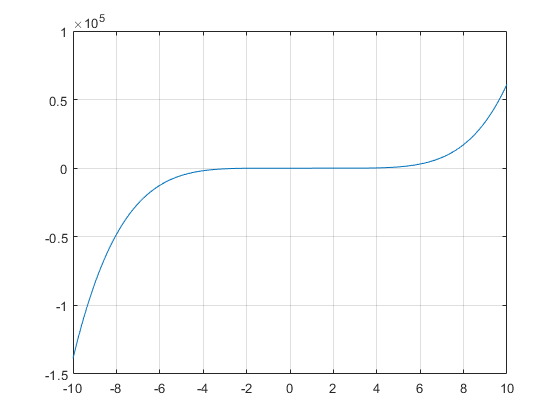

% Dla tego wielomianu wektor będzie wyglądał tak:
wsp = [1 -4 0 13 -1 1];

%wywołanie funkcji roots:
zero_locations = roots(wsp)

%Zwróć uwagę, że uzyskano miejsca zespolone i jedno rzeczywiste - dlatego że akurat ten
%wielomian Ma tylko jedno miejsce zerowe rzeczywiste.

plot([-10:0.1:10], polyval(wsp,[-10:0.1:10])); grid on;

%Spróbuj zmienić ten wielomian na taki który ma same miejsca rzeczywiste i sprawdź 
% działanie kodu.

% W ramach ćwiczenia spróbuj metodą nie dedykowaną dla wielomianów np.
% metodą Newtona znaleźć wszystkie miejsca zerowe wielomianu.

 

## FUNKCJE

function [f] = fsolveFunctionTemplate(x) 
a=0;
b=0;
r=3;

f(1) = (x(1)-a)^2+(x(2)-b)^2-r;
f(2) = x(1)-x(2);
end

function [f,J] = fsolveFunctionTemplateJacobian(x) 
a=0;
b=0;
r=3;

f(1) = (x(1)-a)^2+(x(2)-b)^2-r;
f(2) = x(1)-x(2);

J(1,1) = 2.*x(1);
J(1,2) = 2.*x(2);
J(2,1) = 1;
J(2,2) = -1;
end

function [f] = fzeroFunctionTemplate(x) 
f = x.^2-1;
end

function F = fsolveFunctionExamlple (Y)
%Jeżeli ktoś woli można sobie rozpakować macierz Y na bardziej opisowe
%parametry
u1 = Y(1);
n1e = Y(2);
u2 = Y(3);
n2e = Y(4);

%Dane np. z eksperymentu (mogłyby być to zmienne globalne)
A = 0.000438;       
B = 0.0003;         
C = 0.0000061841;   
D = 0.0000381;  

%Równania
equation1 = n1e*u1 + n2e*u2 - A; 
equation2 = ( (n1e*u1) / (1+u1^2*(14^2)) ) + ( (n2e*u2) / (1+u2^2*(14^2)) ) - B; 
equation3 = n1e*u1^2 + n2e*u2^2 - C; 
equation4 = ( (n1e*u1^2*14) / (1+u1^2*14) ) + ( (n2e*u2^2*14) / (1+u2^2*14) ) - D; 

%Na koniec "pakujemy" do postaci wymaganej przez funkcję
F = [equation1; equation2; equation3; equation4; ];
end

[1]  Brent, R., *Algorithms for Minimization Without Derivatives*, Prentice-Hall,  1973. 

Warszawa, 19.03.2021 r.                                                                                                           **© **K. Król

Sem. 21L